# Transfer Learning with A Deep Neural Network

## Specify options

Set these to true if you want to actually perform the training and testing. Otherwise, we will use pre-computed results.

doTrain = false;
doTest = true;
doTune = false;
createVideoFlag = false;

## Load a pretrained network and inspect it

net = squeezenet %This requires installing a support package!

net =   DAGNetwork with properties:

         Layers: [68×1 nnet.cnn.layer.Layer]
    Connections: [75×2 table]
     InputNames: {'data'}
    OutputNames: {'ClassificationLayer_predictions'}


netName = "squeezenet";

analyzeNetwork(net)

layers = net.Layers

layers =   68×1 Layer array with layers:

     1   'data'                              Image Input                  227×227×3 images with 'zerocenter' normalization
     2   'conv1'                             2-D Convolution              64 3×3×3 convolutions with stride [2  2] and padding [0  0  0  0]
     3   'relu_conv1'                        ReLU                         ReLU
     4   'pool1'                             2-D Max Pooling              3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     5   'fire2-squeeze1x1'                  2-D Convolution              16 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     6   'fire2-relu_squeeze1x1'             ReLU                         ReLU
     7   'fire2-expand1x1'                   2-D Convolution              64 1×1×16 convolutions with stride [1  1] and padding [0  0  0  0]
     8   'fire2-relu_expand1x1'          

targetSize = net.Layers(1).InputSize

targetSize =    227   227     3


sortedLabels = sort(layers(end).ClassNames)

sortedLabels = 1000×1 cell array
    {'Afghan hound'                  }
    {'African chameleon'             }
    {'African crocodile'             }
    {'African elephant'              }
    {'African grey'                  }
    {'African hunting dog'           }
    {'Airedale'                      }
    {'American Staffordshire terrier'}
    {'American alligator'            }
    {'American black bear'           }
    {'American chameleon'            }
    {'American coot'                 }
    {'American egret'                }
    {'American lobster'              }
    {'Angora'                        }
    {'Appenzeller'                   }
    {'Arabian camel'                 }
    {'Arctic fox'                    }
    {'Australian terrier'            }
    {'Band Aid'                      }
    {'Bedlington terrier'            }
    {'Bernese mountain dog'          }
    {'Blenheim spaniel'              }
    {'Border collie'                 }
    {'Border terrier'          

## Test it on an image

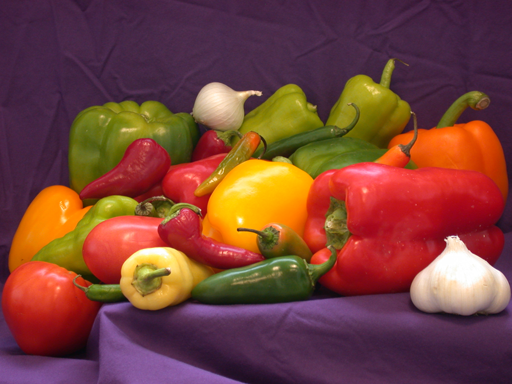

img = imread("peppers.png");
imgLabel = net.classify(imresize(img, targetSize(1:2)));
%
% OR:
% imgLabel = classify(net, imresize(img, targetSize(1:2)));

% display
figure
imshow(img)

disp(netName + " prediction: " + string(imgLabel))

squeezenet prediction: bell pepper


## Try it on another image

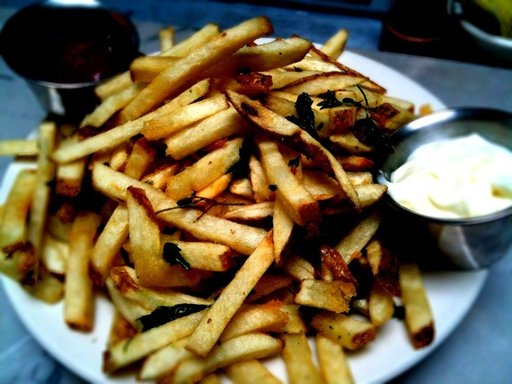

img = imread("17394.jpg");
imgLabel = net.classify(imresize(img, targetSize(1:2)));

% display
imshow(img)

disp(netName + " prediction: " + string(imgLabel))

squeezenet prediction: Dungeness crab


## What were other top choices for classification?

The network also predicts other top choices for the class label of the object. You can use the "predict" method of the network to see other choices that were made.

prediction = predict(net, imresize(img, targetSize(1:2)));
[psorted, pind] = sort(prediction, "descend");
numTopClasses = 5; % show top N choices
TopClasses = net.Layers(end).ClassNames(pind(1:numTopClasses));
Scores = psorted(1:numTopClasses)

Scores = 1×5 single row vector
    0.4879    0.2080    0.1875    0.0292    0.0270


topTable = table(TopClasses, Scores')

topTable = 5×2 table
        TopClasses           Var2  
    ___________________    ________

    {'Dungeness crab' }     0.48791
    {'carbonara'      }     0.20804
    {'king crab'      }     0.18752
    {'plate'          }    0.029236
    {'chocolate sauce'}    0.026975


## Load Image Data

We will use data from the Food101 public dataset, available at [https://data.vision.ee.ethz.ch/cvl/datasets_extra/food-101/](https://data.vision.ee.ethz.ch/cvl/datasets_extra/food-101/). The downloaded dataset has had the following categories extracted from the archive:

- caesar_salad - french_fries - hamburger - pizza - sushi

Unzip the folder of images provided

%unzip(fullfile(pwd, 'Data\foodData\images'))

% Data is 5 different categories of food. How do we read in all of these images?
% Create an imageDataStore to read images. Label all images based on their
% foldernames and include all subfolders in the directory
% Load in input images
imagepath = fullfile(pwd, 'Data\foodData\images');
imds = imageDatastore(imagepath, ...
    "IncludeSubfolders", true, ...
    "LabelSource", "FolderNames");
imds.ReadFcn = @(I)imresize(imread(I), targetSize(1:2));

Error using imageDatastore (line 139)
Cannot find files or folders matching: 'C:\Users\MathWorks\OneDrive - MathWorks\Documents\MATLAB\fromPixelsToModelsNO_DATA_NatResCanada\fromPixelsToModels\Demos\foodData'.


% display # of labels and count of each
imds.countEachLabel
label_class = unique(imds.Labels);
nl = length(label_class);

imds

## We can visually inspect individual sample images

rng(1)
visImds = splitEachLabel(imds, 1, "randomize");

for ii = 1:nl
    subplot(2, ceil(nl/2), ii);
    thisImage = imresize(visImds.readimage(ii), [227 227]);
    imshow(thisImage);
    predictedLabel = net.classify(thisImage);
    title(sprintf("Actual: %s\nPredicted: %s", ...
        char(visImds.Labels(ii)), ...
        predictedLabel), ...
        "interpreter", "none");
end

% We can clearly see that, without further training, the pretrained network
% does not do a good job predicting most of the new images. This is where
% transfer learning will shine and help improve prediction accuracy.

## First we separate the (ground-truthed) images into training/testing

[trainDS, valDS] = splitEachLabel(imds, 0.7, "randomized");

[trainDS, testDS, valDS] = splitEachLabel(imds, 0.7, 0.2, 0.1, "randomized");

## Alter network to fit our desired output.

Perform your network "surgery" by launching the DeepNetworkDesigner app.

deepNetworkDesigner

**Load a Pretrained Network**

- In the app, click **"New"** and select a pretrained network (e.g., **AlexNet**, **ResNet-18**, **GoogLeNet**, etc.).

Click **"Open"** to load the network.

- **Modify the Network for Transfer Learning**

- Identify the **final layers** (usually the classification layers).

- Right-click on the final layers and choose **"Replace Layer"**.

Replace with: 

- A new **fully connected layer** with the number of classes in your dataset.

- A new **classification layer**.

**Modify the Network for Transfer Learning**

- Identify the **final layers** (usually the classification layers).

- Right-click on the final layers and choose **"Replace Layer"**.

Replace with: 

- A new **fully connected layer** with the number of classes in your dataset.

- A new **classification layer**.

**Import Your Data**

- Click **"Data"** > **"Import Data"**.

- Choose your image dataset (e.g., from a folder or `ImageDatastore`).

- Make sure the dataset is labeled and formatted correctly.

**Check Layer Compatibility**

- Click **"Analyze"** to verify the network structure and ensure all layers are compatible with your data.

**Train the Network**

- Click **"Training Options"** to set parameters like: 

- Mini-batch size

- Learning rate

- Number of epochs

- Click **"Train"** to start training.

**Export the Trained Network**

- Once training is complete, click **"Export"** to save the trained network to the MATLAB workspace.

## Now train:

If you get an out of memory error for the GPU, please set the "MiniBatchSize" to a lower value.

pass = 1;
opts = trainingOptions("sgdm", ...
    "ValidationData", valDS, ...
    "Plots", "training-progress", ...
    "MiniBatchSize", 64, ...
    "ValidationPatience", 3);

net = trainNetwork(trainDS, layers_train, opts);
save(fullfile("results", [netName, "TransferLearningPass", num2str(pass), ".mat"]), "net")


imshow(imgFrame)
title(netName + "; InitialLearnRate: " + num2str(opts.InitialLearnRate));
editorwindow

## HOW CAN WE IMPROVE THIS?

### 1) BAYESIAN HYPERPARAMETER TUNING

## HOW CAN WE IMPROVE THIS?

###  2) IMAGE DATA AUGMENTATION

To prevent overfitting and improve training results, oftentimes data augmentation is needed.

## How do we improve this even more?

- More training images

- More complex architectures  *